clear; close; clc;
A = 29

A = 29

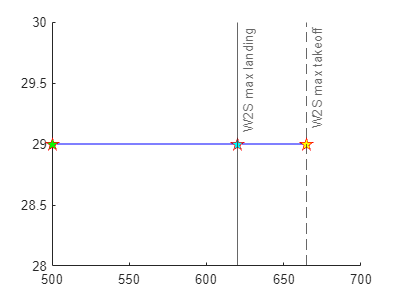

figure

% define design points
W2S_selfLaunch = 500;
W2S_Landing = 620;
W2S_AssistedLaunch = 665;

A = 29;

% plot design line
hold on;
plot([W2S_selfLaunch, W2S_Landing, W2S_AssistedLaunch], [A,A,A], "-b", "DisplayName","Design line");

% plot design points
plot(W2S_selfLaunch,A,'p', 'MarkerFaceColor','green', "MarkerEdgeColor","red",  'MarkerSize',10,  DisplayName='Self Launch');
plot(W2S_Landing,A,'p', 'MarkerFaceColor','cyan', "MarkerEdgeColor","red", 'MarkerSize',10,  DisplayName='Winch/Tow/GOFER fixed ballast')
plot(W2S_AssistedLaunch,A,'p', 'MarkerFaceColor','yellow', "MarkerEdgeColor","red", 'MarkerSize',10,  DisplayName='Winch/Tow/GOFER water ballast')

% plot constraining lines (from wing and pwoer loading diagram)
xline(W2S_AssistedLaunch,"--","W2S max takeoff");
xline(W2S_Landing,"-","W2S max landing");



% line to determin maximum
% xline(670)
% xline(622)
% xline(665,"--")